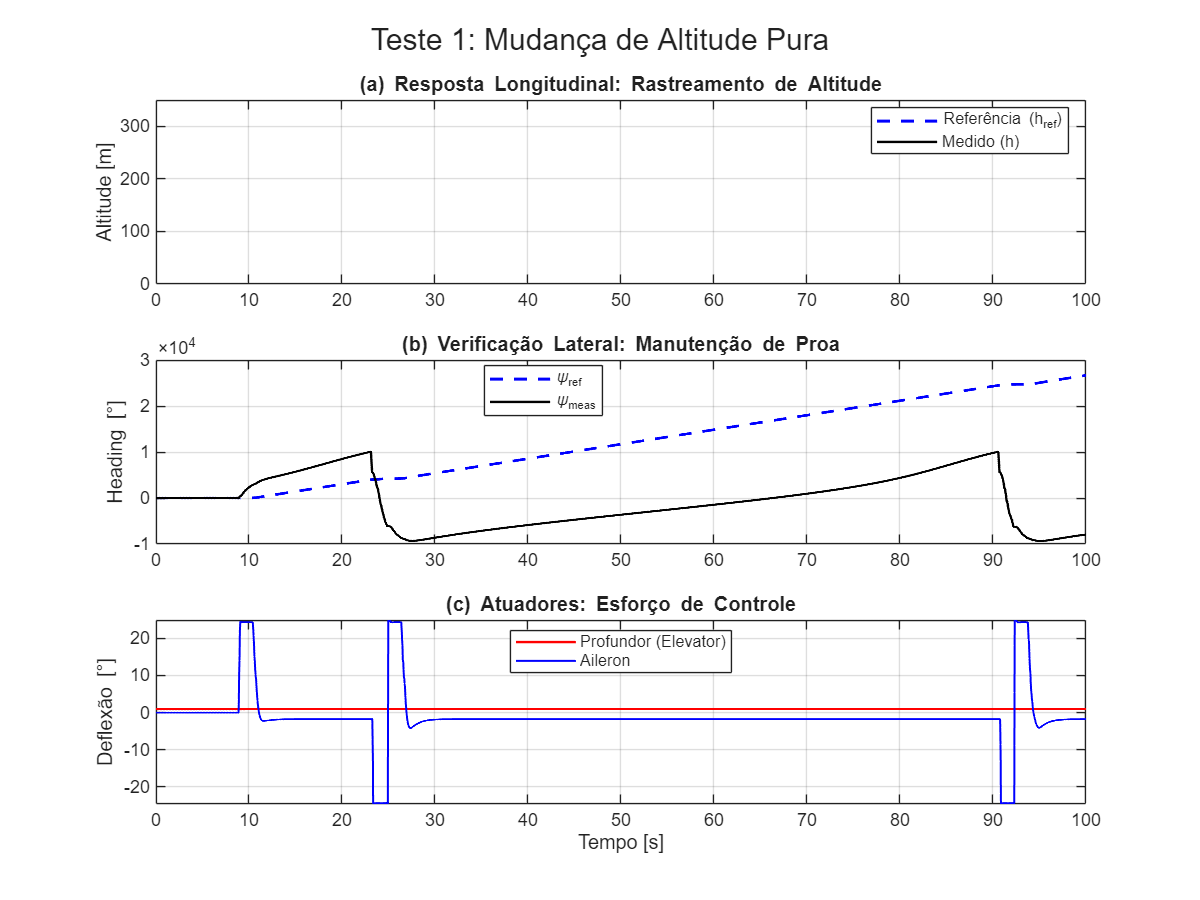

% Script de Plotagem - Teste 1: Validação Longitudinal
% Este script gera visualizações para a manobra de mudança de altitude,
% verificando o rastreamento e o desacoplamento lateral.

% --- Configurações Iniciais ---
% Cria uma nova figura com tamanho adequado para documentos (proporção A4 ou Widescreen)
figure('Name', 'Teste 1: Validação Longitudinal', 'Color', 'w', 'Position', [100 100 800 600]);

% Vetor de tempo (assumindo que out.tout existe no workspace)
% Se não existir, crie um baseado no tamanho: t = 1:length(out.ALT);
if exist('out', 'var') && isfield(out, 'tout')
    t = out.tout;
else
    % Fallback se não encontrar o tempo
    t = linspace(0, 100, length(out.ALT)); % Ajuste o '100' para o tempo final real
end

% --- Subplot 1: Altitude (O foco do teste) ---
subplot(3,1,1);
plot(t, out.ALT(:,1), 'b--', 'LineWidth', 1.5); hold on; % Referência (Azul tracejado)
plot(t, out.ALT(:,2), 'k-', 'LineWidth', 1.2);          % Medido (Preto contínuo)
grid on;
ylabel('Altitude [m]');
title('\bf(a) Resposta Longitudinal: Rastreamento de Altitude');
legend('Referência (h_{ref})', 'Medido (h)', 'Location', 'Best');
xlim([min(t) max(t)]);
axis([0 100 0 350])

% --- Subplot 2: Heading (Prova de Desacoplamento) ---
% Aqui esperamos ver linhas retas, provando que o avião não guinou.
subplot(3,1,2);
plot(t, rad2deg(out.HEADING(:,1)), 'b--', 'LineWidth', 1.5); hold on;
plot(t, rad2deg(out.HEADING(:,2)), 'k-', 'LineWidth', 1.2);
grid on;
ylabel('Heading [\circ]');
title('\bf(b) Verificação Lateral: Manutenção de Proa');
legend('\psi_{ref}', '\psi_{meas}', 'Location', 'Best');
xlim([min(t) max(t)]);
% Dica: Se o erro for microscópico (ex: 1e-9), o MATLAB pode usar notação científica no eixo.

% --- Subplot 3: Esforço de Controle (Elevator vs Aileron) ---
% Mostra que o profundor trabalhou e o aileron dormiu.
subplot(3,1,3);
elev_cmd = rad2deg(out.U.signals.values(:,2)); % Coluna 2 = Elevator
ail_cmd  = rad2deg(out.U.signals.values(:,3)); % Coluna 3 = Aileron

plot(t, elev_cmd, 'r-', 'LineWidth', 1.2); hold on;
plot(t, ail_cmd, 'b-', 'LineWidth', 1.0);
grid on;
xlabel('Tempo [s]');
ylabel('Deflexão [\circ]');
title('\bf(c) Atuadores: Esforço de Controle');
legend('Profundor (Elevator)', 'Aileron', 'Location', 'Best');
xlim([min(t) max(t)]);

% Ajuste fino para não cortar rótulos
sgtitle('Teste 1: Mudança de Altitude Pura');

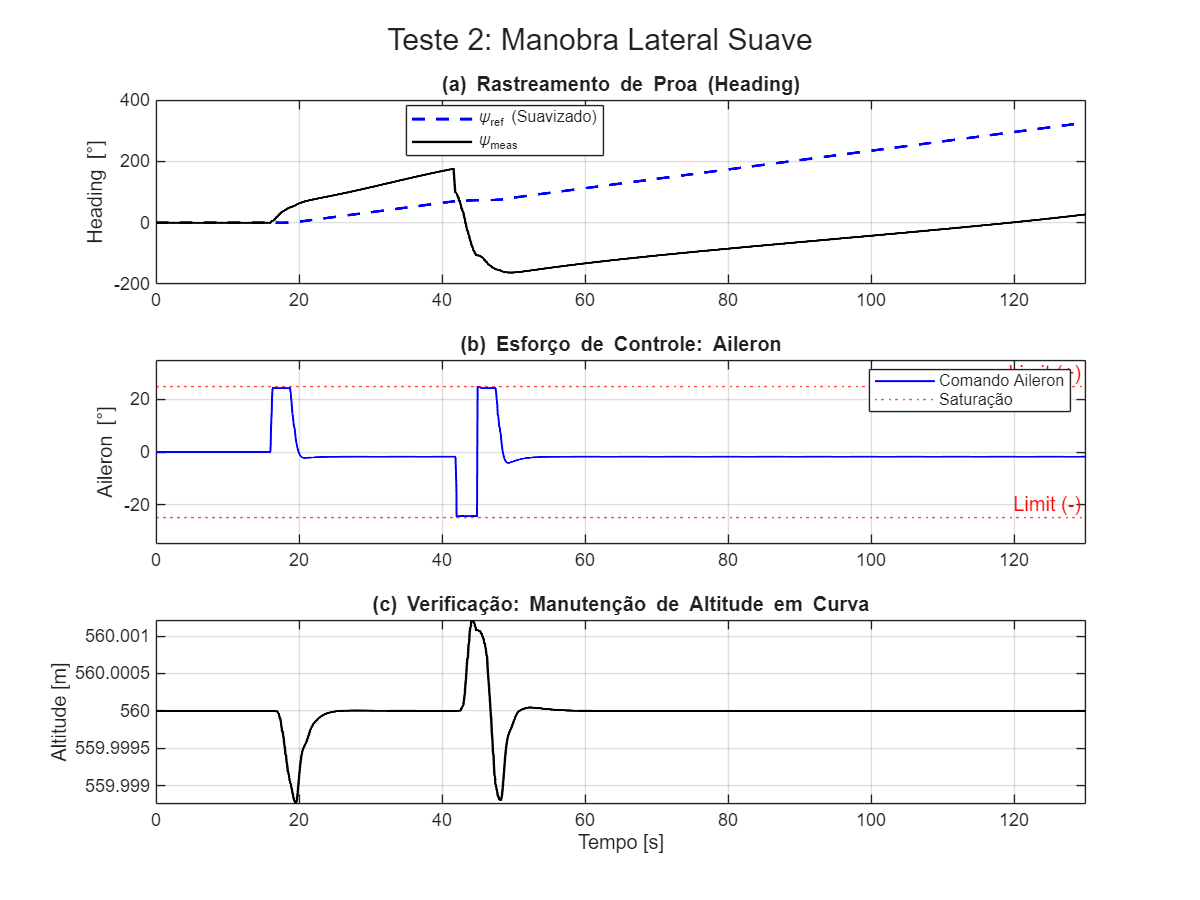

%% Script de Plotagem - Teste 2: Validação Lateral (Dogleg)
% Objetivo: Verificar rastreamento de Heading, suavidade do Guidance 
% e comportamento do atuador (Aileron).

% --- Configurações Iniciais ---
figure('Name', 'Teste 2: Validação Lateral', 'Color', 'w', 'Position', [150 150 800 600]);

% Vetor de tempo (Fallback se out.tout não existir)
if exist('out', 'var') && isfield(out, 'tout')
    t = out.tout;
else
    t = linspace(0, 180, length(out.HEADING)); % Ajuste o tempo final conforme sua simulação
end

% Conversão de Unidades:
% IMPORTANTE: Se seus dados já estiverem em GRAUS no 'out', 
% remova a função 'rad2deg' abaixo. Assumindo Radianos por padrão.
conv_ang = 180/pi; % Fator de conversão (ou 1 se já for graus)

% --- Subplot 1: Heading (A "Prova" da Correção do Guidance) ---
subplot(3,1,1);
% Plota Referência (Guidance)
plot(t, out.HEADING(:,1), 'b--', 'LineWidth', 1.5); hold on;
% Plota Medido (Resposta da Aeronave)
plot(t, out.HEADING(:,2), 'k-', 'LineWidth', 1.2);
grid on;
ylabel('Heading [\circ]');
title('\bf(a) Rastreamento de Proa (Heading)');
legend('\psi_{ref} (Suavizado)', '\psi_{meas}', 'Location', 'Best');
xlim([min(t) 130]);
% Dica: Observe se a linha azul não tem mais "degraus".

% --- Subplot 2: Atuador Lateral (Aileron) ---
subplot(3,1,2);
aileron_cmd = out.U.signals.values(:,3) * conv_ang; % Coluna 3 = Aileron

plot(t, aileron_cmd, 'b-', 'LineWidth', 1.0); hold on;
% Opcional: Desenhar linhas de limite de saturação (ex: +/- 25 graus)
yline(25, 'r:', 'Limit (+)'); 
yline(-25, 'r:', 'Limit (-)');
grid on;
ylabel('Aileron [\circ]');
title('\bf(b) Esforço de Controle: Aileron');
legend('Comando Aileron', 'Saturação', 'Location', 'Best');
xlim([min(t) 130]);
ylim([-35 35]); % Ajuste o zoom para ver bem o sinal

% --- Subplot 3: Altitude (Verificação de Segurança) ---
% Mostra se o avião manteve a altura durante a curva
subplot(3,1,3);
plot(t, out.ALT(:,2), 'k-', 'LineWidth', 1.2);
grid on;
xlabel('Tempo [s]');
ylabel('Altitude [m]');
title('\bf(c) Verificação: Manutenção de Altitude em Curva');
xlim([min(t) 130]);

% Título Geral
sgtitle('Teste 2: Manobra Lateral Suave');

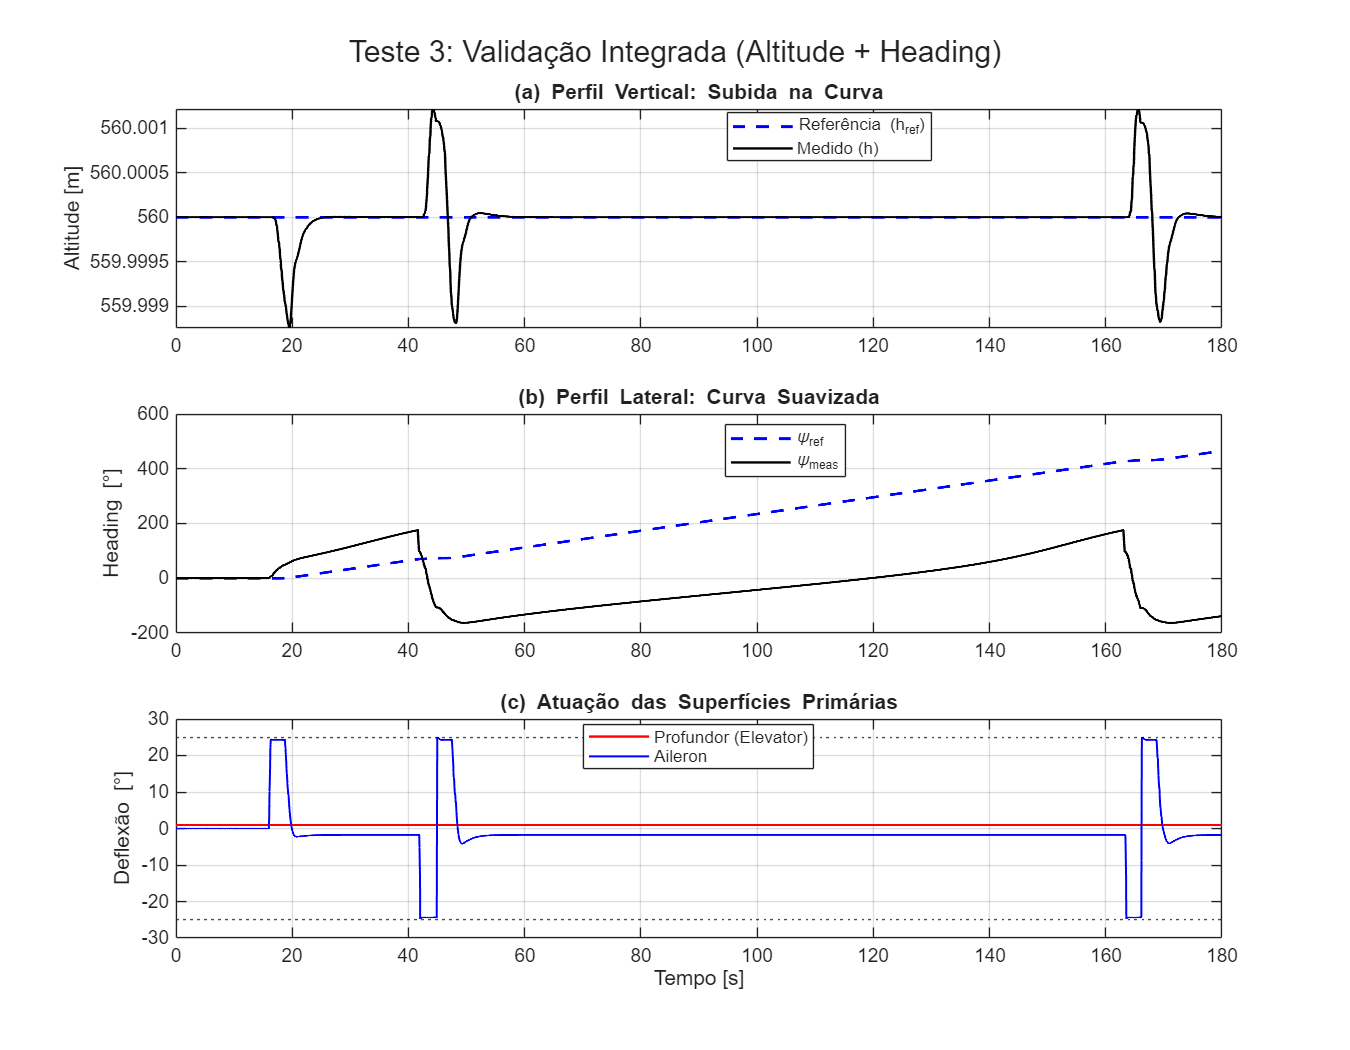


%% Script de Plotagem - Teste 3: Manobra Acoplada (Sem Throttle)
% Objetivo: Validar a correção do envelope de voo e a atuação das superfícies.

% --- Configurações Iniciais ---
figure('Name', 'Teste 3: Superfícies de Controle', 'Color', 'w', 'Position', [100 100 900 700]);

% Vetor de tempo
if exist('out', 'var') && isfield(out, 'tout')
    t = out.tout;
else
    t = linspace(0, 180, length(out.HEADING)); 
end

conv_ang = 180/pi; % Conversão Rad -> Graus

% --- Subplot 1: Trajetória Vertical (Altitude) ---
subplot(3,1,1);
plot(t, out.ALT(:,1), 'b--', 'LineWidth', 1.5); hold on;
plot(t, out.ALT(:,2), 'k-', 'LineWidth', 1.2);
grid on;
ylabel('Altitude [m]');
title('\bf(a) Perfil Vertical: Subida na Curva');
legend('Referência (h_{ref})', 'Medido (h)', 'Location', 'Best');
xlim([min(t) max(t)]);

% --- Subplot 2: Trajetória Lateral (Heading) ---
subplot(3,1,2);
plot(t, out.HEADING(:,1), 'b--', 'LineWidth', 1.5); hold on;
plot(t, out.HEADING(:,2), 'k-', 'LineWidth', 1.2);
grid on;
ylabel('Heading [\circ]');
title('\bf(b) Perfil Lateral: Curva Suavizada');
legend('\psi_{ref}', '\psi_{meas}', 'Location', 'Best');
xlim([min(t) max(t)]);

% --- Subplot 3: Superfícies de Controle (Apenas Aerodinâmica) ---
subplot(3,1,3);

% Extraindo sinais (Col 2 = Elevator, Col 3 = Aileron)
elevator = out.U.signals.values(:,2) * conv_ang; 
aileron  = out.U.signals.values(:,3) * conv_ang; 

plot(t, elevator, 'r-', 'LineWidth', 1.2); hold on;
plot(t, aileron, 'b-', 'LineWidth', 1.0);

% Linhas de limite sugeridas (ajuste se seu limite for diferente de +/- 20 ou 25)
yline(25, 'k:', 'HandleVisibility', 'off'); 
yline(-25, 'k:', 'HandleVisibility', 'off');

grid on;
ylabel('Deflexão [\circ]');
xlabel('Tempo [s]');
title('\bf(c) Atuação das Superfícies Primárias');
legend('Profundor (Elevator)', 'Aileron', 'Location', 'Best');
xlim([min(t) max(t)]);
ylim([-30 30]); % Zoom focado nas superfícies

sgtitle('Teste 3: Validação Integrada (Altitude + Heading)');